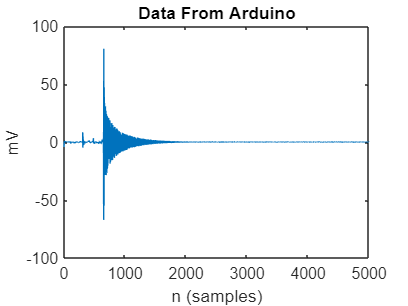

% Bad solution: global variables to store data read from the arduino and
% global boolean value to know when the callback is done reading data
global arduinoData; %#ok<GVMIS>
global doneReadingData; %#ok<GVMIS>
doneReadingData = false;

global samples; %#ok<GVMIS> 
samples = 1000;

% print available serial ports
serialportlist("available");
% if ~exist('arduinoObj', 'var')
    % create new serial port object for the arduino
    arduinoObj = serialport("COM3",57600);
% end
% checks serial interface for termination characters sent by the Arduino
configureTerminator(arduinoObj,"CR/LF");
flush(arduinoObj);

% Arduino object holds serial data
arduinoObj.UserData = struct("Data",[],"Count",1);
% Don't fully understand this line yet, however I'm fairly certain
% That the data being read from the Serial bus is being read in parallel
configureCallback(arduinoObj,"terminator",@readSineWaveData);
% Wait in loop until data is done being read
while(~doneReadingData)
    pause(0.05);
end

% Minimum value to be taken into account for FFT (Used for gating noise)
Th = 0.2;               % Threshold in mV

Fs = samples;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = samples;             % Length of signal
t = (0:L-1)*T;        % Time vector

plot(samples*t(1:end),arduinoData(1:end))
title('Data From Arduino')
xlabel('n (samples)')
ylabel('mV')

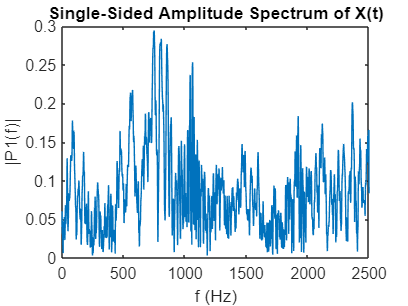

% Arduino Code to convert to mV: float Vout = (float)((adc_data*VFSR*1000)/FSR);     //In  mV

Y = fft(arduinoData);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
% ylim([0, 40])
xlabel('f (Hz)')
ylabel('|P1(f)|')


% flushes and clears serial object
flush(arduinoObj);
clear("arduinoObj");

function readSineWaveData(src, ~)

global arduinoData %#ok<GVMIS> 
global doneReadingData %#ok<GVMIS> 
global samples %#ok<GVMIS> 
% Read the ASCII data from the serialport object.
if (isfloat(str2double(readline(src))))
    data = readline(src);
end

% threshold = 0.8;
% if (str2double(data) > threshold)
%     return;
% end

% Convert the string data to numeric type and save it in the UserData
% property of the serialport object.
src.UserData.Data(end+1) = str2double(data);

% Update the Count value of the serialport object.
src.UserData.Count = src.UserData.Count + 1;



% If 1001 data points have been collected from the Arduino, switch off the
% callbacks and plot the data.
% if src.UserData.Count > 1001
%     configureCallback(src, "off");
%     plot(src.UserData.Data(2:end));
% end
if src.UserData.Count > samples+1
    configureCallback(src, "off");
    arduinoData = src.UserData.Data(2:end);
    doneReadingData = true;
end

end